%Lectura matriu de digits
N=10;
[images, labels] =readMNIST( ...
    'train-images-idx3-ubyte\train-images.idx3-ubyte', ...
    'train-labels-idx1-ubyte\train-labels.idx1-ubyte',N,30000);

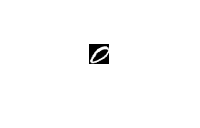

Nft = 120;
vartypes = strings([1,Nft+1]);
vartypes{Nft+1} = 'string';
vartypes(1:Nft) = 'double';
T = table('Size',[N Nft+1],'VariableTypes',vartypes);




for i = 1:N
    im=images(:,:,i); 
    imshow(im)
    [sumRow, sumCol] = pixelCount(im);
    [distRowLeft,distRowRight,distColUp,distColDown] = characterProfile(im);
    
    T{i,1:20} = sumRow;
    T{i,21:40} = sumCol;
    T{i,41:60} = distRowLeft;
    T{i,61:80} = distRowRight;
    T{i,81:100} = distColUp;
    T{i,101:120} = distColDown;
    T.Var121(i) = labels(i);
end